# 实验四

## 系统冲激响应和阶跃响应

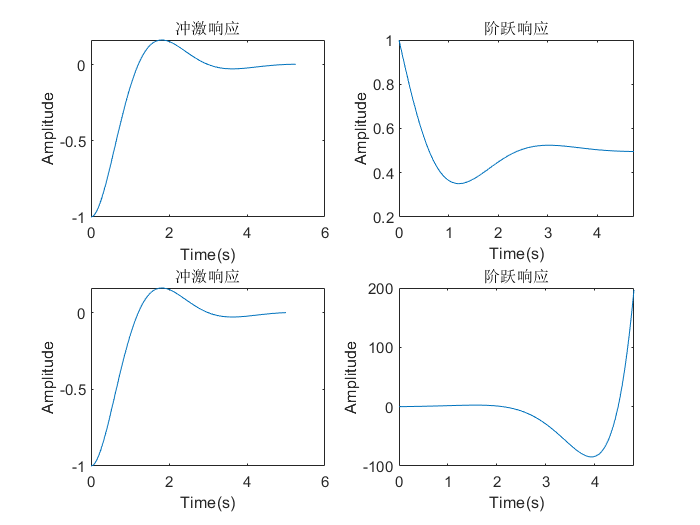

clear, clc

n1 = [1, 1, 2];
d1 = [1, 2, 4];
sys1 = tf(n1, d1);
[y11, t11] = impulse(sys1);
[y12, t12] = step(sys1);
n2 = [1, -1, 1];
d2 = [1, -2, 1, 4];
sys2 = tf(n2, d2);
[y21, t21] = impulse(sys1, 5);
[y22, t22] = step(sys2, 4.8);

figure;
subplot(2, 2, 1); plot(t11, y11); title("冲激响应"); ylabel("Amplitude"); xlabel("Time(s)");
subplot(2, 2, 2); plot(t12, y12); title("阶跃响应"); ylabel("Amplitude"); xlabel("Time(s)");
subplot(2, 2, 3); plot(t21, y21); title("冲激响应"); ylabel("Amplitude"); xlabel("Time(s)");
subplot(2, 2, 4); plot(t22, y22); title("阶跃响应"); ylabel("Amplitude"); xlabel("Time(s)");

## 线性时不变系统线性性质

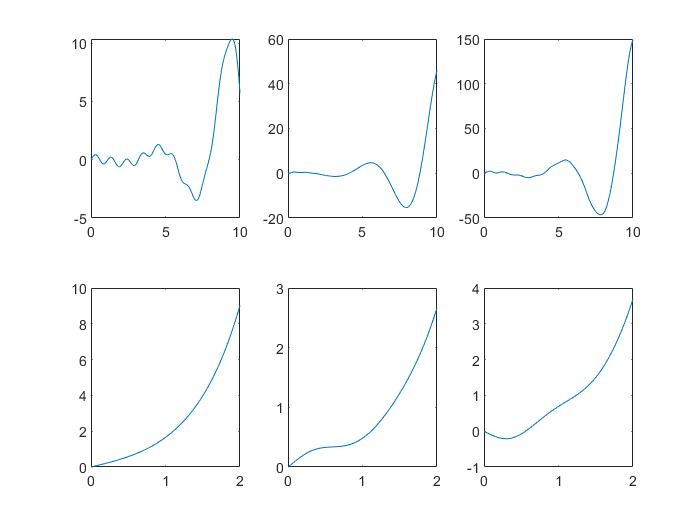

tfn1 = [2, 1];
tfd1 = [1, -1, 2];
sys1 = tf(tfn1, tfd1);
t = 0:0.01:10;
x1 = cos(6.*t);
x2 = exp(-t).*sin(8.*t);
x = 2.*x1 + 3.*x2;
out11 = lsim(sys1, x1, t);
out12 = lsim(sys1, x2, t);
out13 = lsim(sys1, x, t);

figure;
subplot(2, 3, 1); plot(t, out11);
subplot(2, 3, 2); plot(t, out12);
subplot(2, 3, 3); plot(t, out13);

tfn2 = [1, 2, 1];
tfd2 = [1, 0, -3, 1];
sys2 = tf(tfn2, tfd2);
t = 0:0.01:2;
x1 = exp(-2.*t);
x2 = exp(-t).*cos(5.*t);
x = x1 - 2.*x2;
out21 = lsim(sys2, x1, t);
out22 = lsim(sys2, x2, t);
out23 = lsim(sys2, x, t);

subplot(2, 3, 4); plot(t, out21);
subplot(2, 3, 5); plot(t, out22);
subplot(2, 3, 6); plot(t, out23);

## 线性时不变连续系统频率特性

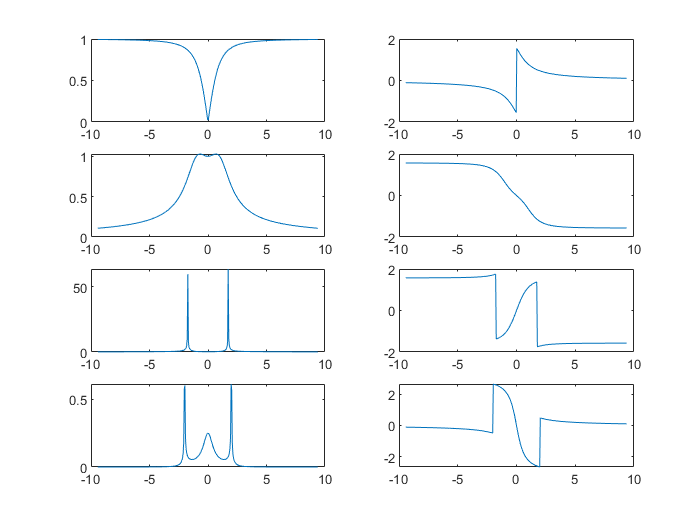

omega = -3*pi:0.05:3*pi;
H1 = h1(omega);
H2 = h2(omega);
H3 = h3(omega);
H4 = h4(omega);
figure;
subplot(4, 2, 1); plot(omega, abs(H1));
subplot(4, 2, 2); plot(omega, angle(H1));
subplot(4, 2, 3); plot(omega, abs(H2));
subplot(4, 2, 4); plot(omega, angle(H2));
subplot(4, 2, 5); plot(omega, abs(H3));
subplot(4, 2, 6); plot(omega, angle(H3));
subplot(4, 2, 7); plot(omega, abs(H4));
subplot(4, 2, 8); plot(omega, angle(H4));

## 离散系统零状态响应

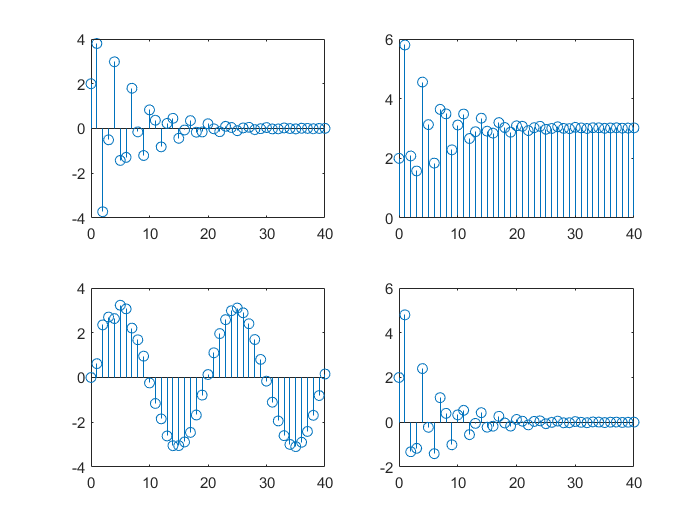

n4 = [2, 5];
d4 = [1, 0.6, 0.72];
n = 0:40;
x3 = sin(n.*pi./10);
x4 = 2.^(-n);

figure;
subplot(2, 2, 1); stem(n, impz(n4, d4, n));
subplot(2, 2, 2); stem(n, stepz(n4, d4, n));
subplot(2, 2, 3); stem(n, filter(n4, d4, x3));
subplot(2, 2, 4); stem(n, filter(n4, d4, x4));

## 离散系统频率特性

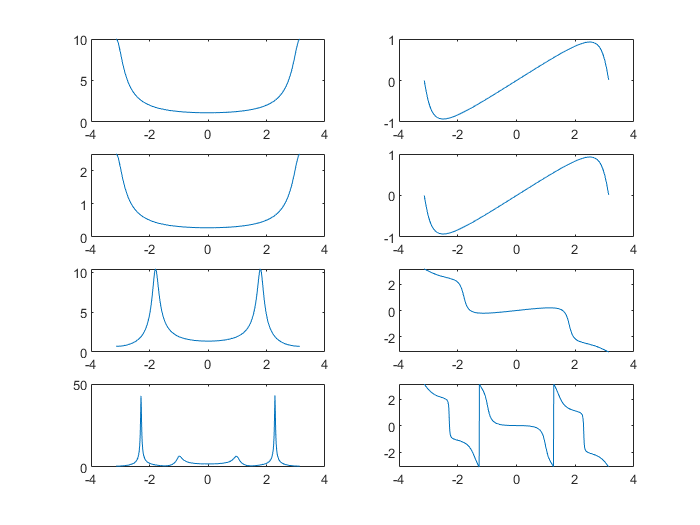

n1 = [2];
d1 = [1, 0.8];
n2 = [0.5, 0];
d2 = [1, 0.8];
n3 = [1, 2];
d3 = [1, 0.4, 0.8];
n4 = [1, 1, 1, 2];
d4 = [1, 0.3, 0.5, 0.1, 0.8];
omega = -pi:0.01:pi;

[H1, w1] = freqz(n1, d1, omega);
[H2, w2] = freqz(n2, d2, omega);
[H3, w3] = freqz(n3, d3, omega);
[H4, w4] = freqz(n4, d4, omega);

figure;
subplot(4, 2, 1); plot(w1, abs(H1));
subplot(4, 2, 2); plot(w1, angle(H1));
subplot(4, 2, 3); plot(w1, abs(H2));
subplot(4, 2, 4); plot(w1, angle(H2));
subplot(4, 2, 5); plot(w1, abs(H3));
subplot(4, 2, 6); plot(w1, angle(H3));
subplot(4, 2, 7); plot(w1, abs(H4));
subplot(4, 2, 8); plot(w1, angle(H4));